
clear; clc; close all
%% Radar parameters
c = physconst('LightSpeed'); %speed of light
BW = 50e6; %bandwidth
fc = 3e9; % carrier frequency
numADC = 256; % # of adc samples
numChirps = 256; % # of chirps per frame

numCPI = 10;
T = 10e-3; % PRI 
PRF = 1/T;
F = numADC/T; % sampling frequency
dt = 1/F; % sampling interval
slope = BW/T;
lambda = c/fc;

N = numChirps*numADC*numCPI; % total # of adc samples
t = linspace(0,T*numChirps*numCPI,N); % time axis, one frame
t_onePulse = 0:dt:dt*numADC-dt;




numTX_x = 2;
numTX_y = 2;

numTX=numTX_x*numTX_y;

numRX_x = 2;
numRX_y = 2;

numRX=numRX_x*numRX_y;

N_L=floor(2*fc/BW);
N_L=(mod(N_L, 2) == 0)*(N_L-1)+(mod(N_L, 2) == 1)*(N_L); % 扩展的虚拟阵列
N_L=1;

Vmax = lambda/(T*4); % Max Unamb velocity m/s

d_y=lambda/2;
d_x= lambda/2;



d_rx = numRX_x*d_x; % dist. between rxs
% d_tx = 4*d_rx; % dist. between txs

% tr_vel=-d_tx/2/T;
tr_vel=0;


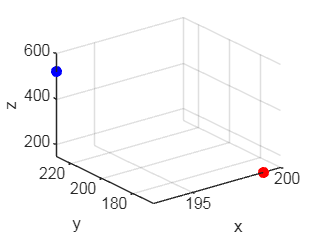


%% Targets

r1_radial = 300;
tar1_theta = 60;
tar1_phi= 40;
r1_x = cosd(tar1_phi)*sind(tar1_theta)*r1_radial;
r1_y = sind(tar1_phi)*sind(tar1_theta)*r1_radial;
r1_z = cosd(tar1_theta)*r1_radial;

v1_radial = 0.1; % velocity 1
v1_x = cosd(tar1_phi)*sind(tar1_theta)*v1_radial;
v1_y = sind(tar1_phi)*sind(tar1_theta)*v1_radial;
v1_z = cosd(tar1_theta)*v1_radial;
r1 = [r1_x r1_y r1_z];


tar1_loc = zeros(length(t),3);
tar1_loc(:,1) = r1(1) + v1_x*t;
tar1_loc(:,2) = r1(2) + v1_y*t;
tar1_loc(:,3) = r1(3) + v1_z*t;

scatter3(tar1_loc(1,1),tar1_loc(1,2),tar1_loc(1,3),'r','filled')
hold on
r2_radial = 600;
tar2_theta = 30;
tar2_phi = 50;
r2_x = cosd(tar2_phi)*sind(tar2_theta)*r2_radial;
r2_y = sind(tar2_phi)*sind(tar2_theta)*r2_radial;
r2_z = cosd(tar2_theta)*r2_radial;

v2_radial = 0.1; % velocity 1
v2_x = cosd(tar2_phi)*sind(tar2_theta)*v2_radial;
v2_y = sind(tar2_phi)*sind(tar2_theta)*v2_radial;
v2_z = cosd(tar2_theta)*v2_radial;
r2 = [r2_x r2_y r2_z];


tar2_loc = zeros(length(t),3);
tar2_loc(:,1) = r2(1) + v2_x*t;
tar2_loc(:,2) = r2(2) + v2_y*t;
tar2_loc(:,3) = r2(3) + v2_z*t;
scatter3(tar2_loc(1,1),tar2_loc(1,2),tar2_loc(1,3),'blue','filled')
xlabel('x');
ylabel('y');
zlabel('z');
hold off

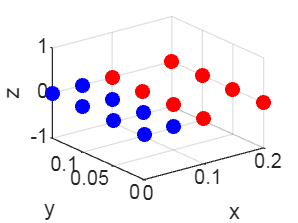


tx_loc = cell(numTX,Ny);
tx_loc_t=cell(numTX,Ny);
for j=1:Ny
    for i = 1:numTX
        tx_loc{i,j} = [(i-1)*d_tx (j-1)*d_y 0];
        tx_loc_t{i,j}=zeros(length(t),3);
        tx_loc_t{i,j}(:,1)=tr_vel*t+tx_loc{i,j}(1);
        tx_loc_t{i,j}(:,2)=tx_loc{i,j}(2);
        tx_loc_t{i,j}(:,3)=tx_loc{i,j}(3);
    
        scatter3(tx_loc{i,j}(1),tx_loc{i,j}(2),tx_loc{i,j}(3),'b','filled')
       hold on
    end
end

rx_loc = cell(numRX,Ny);
rx_loc_t=cell(numRX,Ny);
for j = 1 : Ny
    for i = 1 : numRX
        rx_loc{i,j} = [tx_loc{numTX,1}(1)+d_tx+(i-1)*d_rx (j-1)*d_y 0];
        rx_loc_t{i,j}=zeros(length(t),3);
        rx_loc_t{i,j}(:,1)=tr_vel*t+rx_loc{i,j}(1);
        rx_loc_t{i,j}(:,2)=rx_loc{i,j}(2);
        rx_loc_t{i,j}(:,3)=rx_loc{i,j}(3);
        scatter3(rx_loc{i,j}(1),rx_loc{i,j}(2),rx_loc{i,j}(3),'r','filled')
    end
end
xlabel('x');
ylabel('y');
zlabel('z');

%% TX

delays_tar1 = cell(numTX,numRX,Ny);
delays_tar2 = cell(numTX,numRX,Ny);
for k = 1:Ny
    for i = 1:numTX
        for j = 1:numRX
            delays_tar1{i,j,k} = (vecnorm(tar1_loc-rx_loc_t{j,k},2,2) ...
                            +vecnorm(tar1_loc-tx_loc_t{i,k},2,2))/c; 
            delays_tar2{i,j,k} = (vecnorm(tar2_loc-rx_loc_t{j,k},2,2) ...
                            +vecnorm(tar2_loc-tx_loc_t{i,k},2,2))/c;
        end
    end
end


% r1_at_t = cell(numTX,numRX);
% r2_at_t = cell(numTX,numRX);
% tar1_angles = cell(numTX,numRX);
% tar2_angles = cell(numTX,numRX);
% tar1_velocities = cell(numTX,numRX);
% tar2_velocities = cell(numTX,numRX);


%% Complex signal
phase = @(tx,fx) 2*pi*(fx.*tx+slope/2*tx.^2); % transmitted
% phase2 = @(tx,fx,r,v) 2*pi*(2*fx*r/c+tx.*(2*fx*v/c + 2*slope*r/c)); % downconverted

% mixed1 = cell(numTX,numRX);
% mixed2 = cell(numTX,numRX);
mixed = cell(numTX,numRX,Ny);
for l = 1:Ny
    for i = 1:numTX
        for j = 1:numRX
            disp(['Processing Channel: ' num2str(j) '/' num2str(numRX)]);
            for k = 1:numChirps*numCPI
                phase_t = phase(t_onePulse,fc);
                phase_1 = phase(t_onePulse-delays_tar1{i,j,l}(k*numADC),fc); % received
                phase_2 = phase(t_onePulse-delays_tar2{i,j,l}(k*numADC),fc);
                
                signal_t((k-1)*numADC+1:k*numADC) = exp(1j*phase_t);
                signal_1((k-1)*numADC+1:k*numADC) = exp(1j*(phase_t - phase_1));
                signal_2((k-1)*numADC+1:k*numADC) = exp(1j*(phase_t - phase_2));
            end
            mixed{i,j,l} = signal_1 + signal_2;
        end
    end
end

Processing Channel: 1/2
Processing Channel: 2/2
Processing Channel: 1/2
Processing Channel: 2/2
Processing Channel: 1/2
Processing Channel: 2/2
Processing Channel: 1/2
Processing Channel: 2/2
Processing Channel: 1/2
Processing Channel: 2/2
Processing Channel: 1/2
Processing Channel: 2/2
Processing Channel: 1/2
Processing Channel: 2/2
Processing Channel: 1/2
Processing Channel: 2/2







% fr1 = 2*r1(2)*slope/c; 
% fr2 = 2*r2(2)*slope/c;
% fd1 = 2*v1_radial*fc/c; % doppler freq
% fd2 = 2*v2_radial*fc/c;
% f_if1 = fr1 + fd1; % beat or IF freq
% f_if2 = fr2 + fd2;

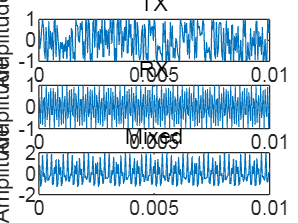


figure
subplot(3,1,1)
p1 = plot(t, real(signal_t));
title('TX')
xlim([0 0.1e-1])
xlabel('Time (sec)');
ylabel('Amplitude');
subplot(3,1,2)
p2 = plot(t, real(signal_1));
title('RX')
xlim([0 0.1e-1])
xlabel('Time (sec)');
ylabel('Amplitude');
subplot(3,1,3)
p3 = plot(t,real(mixed{1,1,1}));
title('Mixed')
xlim([0 0.1e-1])
xlabel('Time (sec)');
ylabel('Amplitude');

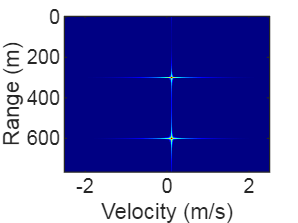


%% Post processing - 2-D FFT
% size(cat(3,mixed{:}))



RDC = reshape(cat(3,mixed{:}),numADC,numChirps*numCPI,numRX*numTX*Ny); % radar data cube

RDC_plus=zeros(numADC,(numChirps-(N_L-1))*numCPI,(numRX*numTX+N_L-1)*Ny);
for l = 1:Ny
    for i = 1:numCPI
        RDC_plus(:,(1:(numChirps-(N_L-1)))+(i-1)*(numChirps-(N_L-1)), ...
                    ((N_L-1)/2+1:(N_L-1)/2+1+numRX*numTX-1)+(l-1)*(numRX*numTX+N_L-1))=...
            RDC(:, (((N_L-1)/2+1):(numChirps-(N_L-1)/2))+(i-1)*(numChirps), ...
            (1:(numRX*numTX))+(l-1)*(numRX*numTX));
        for j = 1:(N_L-1)/2
            for k = 1:numChirps-(N_L-1)
                RDC_plus(:,k+(i-1)*(numChirps-(N_L-1)),(N_L-1)/2+1-j+(l-1)*(numRX*numTX+N_L-1))=RDC(:,(k+(N_L-1)/2+j)+(numChirps*(i-1)),1+(l-1)*(numRX*numTX));
                RDC_plus(:,k+(i-1)*(numChirps-(N_L-1)),(N_L-1)/2+1+numRX*numTX-1+j+(l-1)*(numRX*numTX+N_L-1))=RDC(:,(k+(N_L-1)/2-j)+(numChirps*(i-1)),numRX*numTX+(l-1)*(numRX*numTX));      
            end        
        end                            
    end
end

numChirps_new=(numChirps-(N_L-1));

DFmax = 1/2*PRF; % = Vmax/(c/fc/2); % Max Unamb Dopp Freq
dR = c/(2*BW); % range resol
Rmax = F*c/(2*slope); % TI's MIMO Radar doc
Rmax2 = c/2/PRF; % lecture 2.3
dV = lambda/(2*numChirps*T); % velocity resol, lambda/(2*framePeriod)

N_Dopp = numChirps_new; % length of doppler FFT
N_range = numADC; % length of range FFT
N_azimuth = (numRX*numTX+N_L-1)*Ny;
R = 0:dR:Rmax-dR; % range axis
V = linspace(-Vmax, Vmax, numChirps_new); % Velocity axis
ang_phi = -180:180; % angle axis
ang_theta=0:180;

RDMs = zeros(numADC,numChirps_new,(numRX*numTX+N_L-1)*Ny,numCPI);
for i = 1:numCPI
    RD_frame = RDC_plus(:,(i-1)*numChirps_new+1:i*numChirps_new,:);
    RDMs(:,:,:,i) = fftshift(fft2(RD_frame,N_range,N_Dopp),2);
end




figure
imagesc(V,R,20*log10(abs(RDMs(:,:,1,1))/max(max(abs(RDMs(:,:,1,1))))));
colormap(jet(256))
% set(gca,'YDir','normal')
clim = get(gca,'clim');
caxis([clim(1)/2 0])
xlabel('Velocity (m/s)');
ylabel('Range (m)');

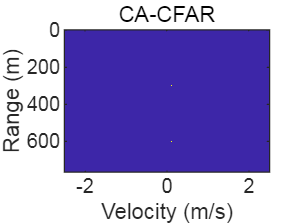


%% CA-CFAR

numGuard = 2; % # of guard cells
numTrain = numGuard*2; % # of training cells
P_fa = 1e-5; % desired false alarm rate 
SNR_OFFSET = -5; % dB
RDM_dB = 10*log10(abs(RDMs(:,:,1,1))/max(max(abs(RDMs(:,:,1,1)))));

[RDM_mask, cfar_ranges, cfar_dopps, K] = ca_cfar(RDM_dB, numGuard, numTrain, P_fa, SNR_OFFSET);
cfar_ranges_real=(cfar_ranges-1)*3;
figure
h=imagesc(V,R,RDM_mask);
xlabel('Velocity (m/s)')
ylabel('Range (m)')
title('CA-CFAR')

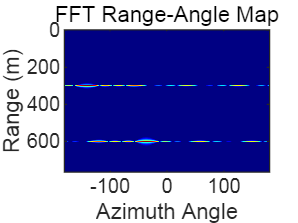


%% Angle Estimation - FFT

rangeFFT = fft(RDC_plus(:,1:numChirps_new,:),numChirps_new);

angleFFT = fftshift(fft(rangeFFT,length(ang_phi),3),3);
range_az = squeeze(sum(angleFFT,2)); % range-azimuth map

figure
colormap(jet)
imagesc(ang_phi,R,20*log10(abs(range_az)./max(abs(range_az(:))))); 
xlabel('Azimuth Angle')
ylabel('Range (m)')
title('FFT Range-Angle Map')
set(gca,'clim', [-35, 0])

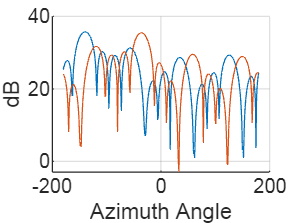


doas = zeros(K,361); % direction of arrivals
figure
hold on; grid on;
for i = 1:K
    doas(i,:) = fftshift(fft(rangeFFT(cfar_ranges(i),cfar_dopps(i),:),length(ang_phi)));
    plot(ang_phi,10*log10(abs(doas(i,:))))
end
xlabel('Azimuth Angle')
ylabel('dB')


% figure
% hold on; grid on;
% for i = 1:K
%     plot(ang_ax,abs(doas(i,:)))
% end
% xlabel('Azimuth Angle')



%% Angle Estimation - MUSIC Pseudo Spectrum


M = numCPI; % # of snapshots
a1=zeros((numRX*numTX+N_L-1)*Ny,length(ang_theta),length(ang_phi));
for k = 1:numRX*numTX+N_L-1
    for l = 1:Ny
       for i=1:length(ang_theta)
            for j=1:length(ang_phi)
                % a1(k+(l-1)*(numRX*numTX+N_L-1),i,j ...
                %     )=exp(-1i*2*pi*(d_y*(l-1)*cos(ang_phi(j).'*pi/180)*sin(ang_theta(i).'*pi/180) ...
                %     +d_tx*(k-1)*sin(ang_phi(j).'*pi/180)*sin(ang_theta(i).'*pi/180)));
                a1(k+(l-1)*(numRX*numTX+N_L-1),i,j ...
                    )=exp(-1i*2*pi*(d_y*(l-1)*sind(ang_phi(j))*sind(ang_theta(i)) ...
                                   +d_tx*(k-1)*cosd(ang_phi(j))*sind(ang_theta(i)) )/lambda );
            end
       end
    end
end






music_spectrum=zeros(K,length(ang_theta),length(ang_phi));
for i = 1:K
    Rxx = zeros((numRX*numTX+N_L-1)*Ny,(numRX*numTX+N_L-1)*Ny);
    A = squeeze(RDMs(cfar_ranges(i),cfar_dopps(i),:,1));
    Rxx = Rxx + (A*A');

    % for m = 1:M
    %    A = squeeze(RDMs(cfar_ranges(i),cfar_dopps(i),:,m));
    %    Rxx = Rxx + 1/M * (A*A');
    % end

    [Q,D] = eig(Rxx); % Q: eigenvectors (columns), D: eigenvalues
    [D, I] = sort(diag(D),'descend');
    Q = Q(:,I); % Sort the eigenvectors to put signal eigenvectors first
    Qs = Q(:,1); % Get the signal eigenvectors
    Qn = Q(:,2:end); % Get the noise eigenvectors
    for j = 1:length(ang_theta)
        for k = 1:length(ang_phi)
            music_spectrum(i,j,k)=(a1(:,j,k)'*a1(:,j,k))/(a1(:,j,k)'*(Qn*Qn')*a1(:,j,k));
            % music_spectrum(i,j,k)=1/(a1(:,j,k)'*(Qn*Qn')*a1(:,j,k));
        end    
    end
end

% a1(:,j,k)'*a1(:,j,k)
% (a1(:,j,k)'*a1(:,j,k))/(a1(:,j,k)'*(Qn*Qn')*a1(:,j,k))


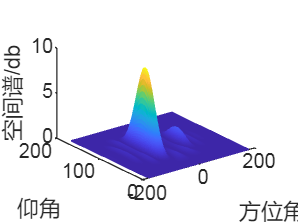

% reshape(music_spectrum(1,:,:),length(ang_theta),length(ang_phi));
figure;
% mesh(10*log10(abs(reshape(music_spectrum(1,:,:),length(ang_theta),length(ang_phi)))));
mesh(ang_phi,ang_theta,10*log10(abs(squeeze(music_spectrum(1,:,:)))));
 
xlabel('方位角');ylabel('仰角');
zlabel('空间谱/db');
grid;

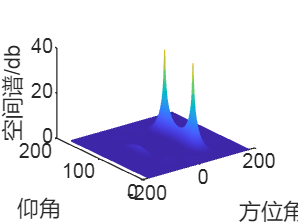

figure;
% mesh(10*log10(abs(reshape(music_spectrum(1,:,:),length(ang_theta),length(ang_phi)))));
mesh(ang_phi,ang_theta,10*log10(abs(squeeze(music_spectrum(2,:,:)))));
 
xlabel('方位角');ylabel('仰角');
zlabel('空间谱/db');
grid;

figure;
% mesh(10*log10(abs(reshape(music_spectrum(1,:,:),length(ang_theta),length(ang_phi)))));
mesh(ang_phi,ang_theta,10*log10(abs(reshape(music_spectrum(3,:,:),length(ang_theta),length(ang_phi)))));

位置 1 处的索引超出数组边界。索引不能超过 2。

 
xlabel('方位角');ylabel('仰角');
zlabel('空间谱/db');
grid;

figure;
% mesh(10*log10(abs(reshape(music_spectrum(1,:,:),length(ang_theta),length(ang_phi)))));
mesh(ang_phi,ang_theta,10*log10(abs(reshape(music_spectrum(4,:,:),length(ang_theta),length(ang_phi)))));
 
xlabel('方位角');ylabel('仰角');
zlabel('空间谱/db');
grid;

% save('plane_20250321_0111.mat',  '-v7.3');


spectrum_data = 10 * log10(abs(reshape(music_spectrum(1,:,:), length(ang_theta), length(ang_phi))));

% 找到最大值及其索引
[max_value, max_index] = max(spectrum_data(:));
[row, col] = ind2sub(size(spectrum_data), max_index);

% 获取对应的角度
theta_max = ang_theta(row);
phi_max = ang_phi(col);

% 输出结果
fprintf('最高点坐标: (Theta: %.2f, Phi: %.2f), 强度: %.2f dB\n', theta_max, phi_max, max_value);

%% Point Cloud



[~, ang] = max(music_spectrum(2,:,:));
a_phi_1 = ang_phi(ang(2));
a_theta_1=ang_theta(ang(1));

[~, I] = max(music_spectrum(1,:));
angle2 = ang_phi(I);

coor1 = [cfar_ranges_real(2)*sind(angle1) cfar_ranges_real(2)*cosd(angle1) 0];
coor2 = [cfar_ranges_real(1)*sind(angle2) cfar_ranges_real(1)*cosd(angle2) 0];
figure
hold on;
title('3D Coordinates (Point Cloud) of the targets')
scatter3(coor1(1),coor1(2),coor1(3),100,'m','filled','linewidth',9)
scatter3(coor2(1),coor2(2),coor2(3),100,'b','filled','linewidth',9)
xlabel('Range (m) X')
ylabel('Range (m) Y')
zlabel('Range (m) Z')


%% MUSIC Range-AoA map
rangeFFT = fft(RDC_plus);
for i = 1:N_range
    Rxx = zeros(numRX*numTX+N_L-1,numRX*numTX+N_L-1);
    for m = 1:M
       A = squeeze(sum(rangeFFT(i,(m-1)*numChirps_new+1:m*numChirps_new,:),2));
       Rxx = Rxx + 1/M * (A*A');
    end
%     Rxx = Rxx + sqrt(noise_pow/2)*(randn(size(Rxx))+1j*randn(size(Rxx)));
    [Q,D] = eig(Rxx); % Q: eigenvectors (columns), D: eigenvalues
    [D, I] = sort(diag(D),'descend');
    Q = Q(:,I); % Sort the eigenvectors to put signal eigenvectors first
    Qs = Q(:,1); % Get the signal eigenvectors
    Qn = Q(:,2:end); % Get the noise eigenvectors

    for k=1:length(ang_phi)
        music_spectrum2(k)=(a1(:,k)'*a1(:,k))/(a1(:,k)'*(Qn*Qn')*a1(:,k));
    end
    
    range_az_music(i,:) = music_spectrum2;
end

figure
colormap(jet)
imagesc(ang_phi,R,20*log10(abs(range_az_music)./max(abs(range_az_music(:))))); 
xlabel('Azimuth')
ylabel('Range (m)')
title('MUSIC Range-Angle Map')
clim = get(gca,'clim');


%% Angle Estimation - Compressed Sensing

numTheta = length(ang_phi); % divide FOV into fine grid
B = a1; % steering vector matrix or dictionary, also called basis matrix

figure
hold on; grid on;
title('Angle Estimation with Compressed Sensing')
xlabel('Azimuth')
ylabel('dB')
for i = 1:K
    A = squeeze(RDMs(cfar_ranges(i),cfar_dopps(i),:,1));
    cvx_begin
        variable s(numTheta) complex; %alphax(numTheta,1) phix(numTX*numRX,numTheta)...

        minimize(norm(s,1))
        norm(A-B*s,2) <= 1;
    cvx_end
    cvx_status
    cvx_optval

    plot(ang_phi,10*log10(abs(s)))
end

